# Check response autocorrelations

Load data:

clear;
clc;

data_struct = loadData()

data_struct =   Map with properties:

        Count: 61
      KeyType: char
    ValueType: any


% subjects = {'01RoYi','02XiHo','03JaVe','04NiSi','05PeYa','06KuSh',...
%     '07AnWo','08LiBa', '09KeVa', '10MaIv', '11YaSi', '12JaGu',...
%     '13ChSc','14SaMc','15ChFi', '16JoDa', '17IvSi','18LuHe','19ElBo','20MiLa',...
%     '21ShZh'};
subjects = {'19ElBo','12JaGu','08LiBa','14SaMc','23InMa','24WePi','15ChFi'}

subjects = 1×7 cell array
    {'19ElBo'}    {'12JaGu'}    {'08LiBa'}    {'14SaMc'}    {'23InMa'}    {'24WePi'}    {'15ChFi'}


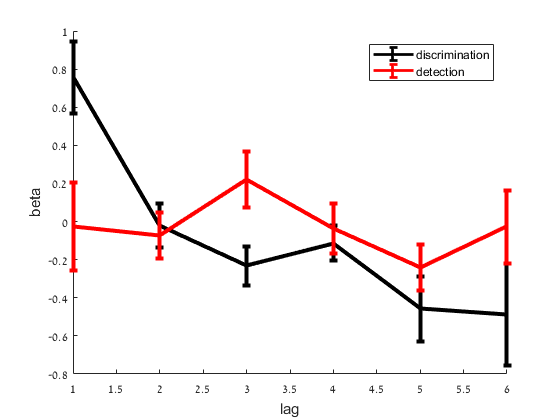

Dis_Coeffs = [];
Det_Coeffs = [];

for s=1:length(subjects)
    subj = data_struct(subjects{s});
    DisMat = [];
    DetMat = [];
    for i = 1:6
        DisVec = [];
        DetVec = [];
        for block = 0:40:160
            DisVec = [DisVec; subj.DisResp([i+block:i+block+29])];
            DetVec = [DetVec; subj.DetResp([i+block:i+block+29])];
        end
        DisMat = [DisMat DisVec];
        DetMat = [DetMat DetVec];
    end
    
    Dis_B = mnrfit(DisMat(:,1:5), DisMat(:,6)+1);
    Det_B = mnrfit(DetMat(:,1:5), DetMat(:,6)+1);
    Dis_Coeffs = [Dis_Coeffs Dis_B];
    Det_Coeffs = [Det_Coeffs Det_B];
end

    figure
    hold on
    errorbar(mean(Dis_Coeffs'),std(Dis_Coeffs')/sqrt(length(subjects)),'k','LineWidth',3);
    errorbar(mean(Det_Coeffs'),std(Det_Coeffs')/sqrt(length(subjects)),'r','LineWidth',3);
    legend('discrimination','detection')
    xlabel('lag');
    ylabel('beta')